# Lab 3 - Mariotte Bottle

clear;
clc;

## Set measurements data

bottle = 6

bottle = 6

hole = 0.4

hole = 0.4000


areaBottle = pi * ((bottle/2)^2)

areaBottle = 28.2743

areaHole = pi * ((hole/2)^2)

areaHole = 0.1257


areas = areaBottle / areaHole

areas = 225.0000

## Load files

v1 = 'https://raw.githubusercontent.com/cararm4073/tec-archive/refs/heads/main/university/EF26/F1008/Lab3/video1.csv'

v1 = 'https://raw.githubusercontent.com/cararm4073/tec-archive/refs/heads/main/university/EF26/F1008/Lab3/video1.csv'

v2 = 'https://raw.githubusercontent.com/cararm4073/tec-archive/refs/heads/main/university/EF26/F1008/Lab3/video2.csv'

v2 = 'https://raw.githubusercontent.com/cararm4073/tec-archive/refs/heads/main/university/EF26/F1008/Lab3/video2.csv'

v3 = 'https://raw.githubusercontent.com/cararm4073/tec-archive/refs/heads/main/university/EF26/F1008/Lab3/video3.csv'

v3 = 'https://raw.githubusercontent.com/cararm4073/tec-archive/refs/heads/main/university/EF26/F1008/Lab3/video3.csv'

v4 = 'https://raw.githubusercontent.com/cararm4073/tec-archive/refs/heads/main/university/EF26/F1008/Lab3/video4.csv'

v4 = 'https://raw.githubusercontent.com/cararm4073/tec-archive/refs/heads/main/university/EF26/F1008/Lab3/video4.csv'

v5 = 'https://raw.githubusercontent.com/cararm4073/tec-archive/refs/heads/main/university/EF26/F1008/Lab3/video5.csv'

v5 = 'https://raw.githubusercontent.com/cararm4073/tec-archive/refs/heads/main/university/EF26/F1008/Lab3/video5.csv'

vMean = 'https://raw.githubusercontent.com/cararm4073/tec-archive/refs/heads/main/university/EF26/F1008/Lab3/videoMean.csv';

%Without extra heading from tracker
data1 = readtable(v1);
%rename column data to avoid weird errors
data1.Properties.VariableNames(1:2) = {'t','y'};
data1 = rmmissing(data1);

%%Extra header or row from tracker, delete it and rename for ease. Happens with files 2 3 and 5
data2 = readtable(v2, 'NumHeaderLines', 1);
data2.Properties.VariableNames(1:2) = {'t','y'};
data2 = rmmissing(data2);

data3 = readtable(v3, 'NumHeaderLines', 1);
data3.Properties.VariableNames(1:2) = {'t','y'};
data3 = rmmissing(data3);

data4 = readtable(v4);

data4 = data4(:,1:2);
data4.Properties.VariableNames = {'t','y'};
data4 = rmmissing(data4);

data5 = readtable(v5, 'NumHeaderLines', 1);
data5.Properties.VariableNames(1:2) = {'t','y'};
data5 = rmmissing(data5);

dataMean = readtable(vMean);

dataMean.Properties.VariableNames(1:2) = {'t','y'};
dataMean = rmmissing(dataMean);

## Load data

t1 = data1.t;
y1 = data1.y;

t2 = data2.t;
y2 = data2.y;

t3 = data3.t;
y3 = data3.y;

t4 = data4.t;
y4 = data4.y;

t5 = data5.t;
y5 = data5.y;

tMean = dataMean.t;
yMean = dataMean.y;

## Maths

With the derivatives for height (y) respecto to time, obtain the velocity in which the water decreases

vLevel1 = -gradient(y1, t1);
vLevel2 = -gradient(y2, t2);
vLevel3 = -gradient(y3, t3);
vLevel4 = -gradient(y4, t4);
vLevel5 = -gradient(y5, t5);
vLevelMean = -gradient(yMean, tMean);

Output velocities or efflux velocities

vOut1 = vLevel1 * areas;
vOut2 = vLevel2 * areas;
vOut3 = vLevel3 * areas;
vOut4 = vLevel4 * areas;
vOut5 = vLevel5 * areas;
vOutMean = vLevelMean * areas;

## **Times**

Exact times in which the water passes from being above the top  (of the bottom) of the straw to where there is no longer straw

change1 = 113.969;
change2 = 61.927;
change3 = 78.000;
change4 = 60.667;
change5 = 82.667;
changeMean = mean([change1 change2 change3 change4 change5]);

Times in which the change between both regimes happen, transition windows

mariotteEnd1 = 113.620;
torricelliStart1 = 114.475;

mariotteEnd2 = 61.353;
torricelliStart2 = 62.034;

mariotteEnd3 = 77.333;
torricelliStart3 = 78.667;

mariotteEnd4 = 60.000;
torricelliStart4 = 61.333;

mariotteEnd5 = 82.000;
torricelliStart5 = 83.333;

## Plotting

### Mean case

Water velocity vs time

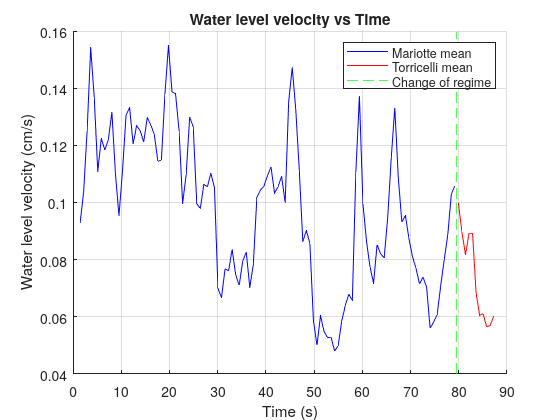

figure();
hold on;
plot(tMean(tMean < changeMean), vLevelMean(tMean < changeMean), 'b-', 'DisplayName', 'Mariotte mean');
plot(tMean(tMean > changeMean), vLevelMean(tMean > changeMean), 'r-', 'DisplayName', 'Torricelli mean');
title('Water level velocity vs Time');
xlabel("Time (s)");
ylabel("Water level velocity (cm/s)");
xline(changeMean, '--g', 'DisplayName', 'Change of regime');
legend();
grid on;
hold off;

Output velocity vs time

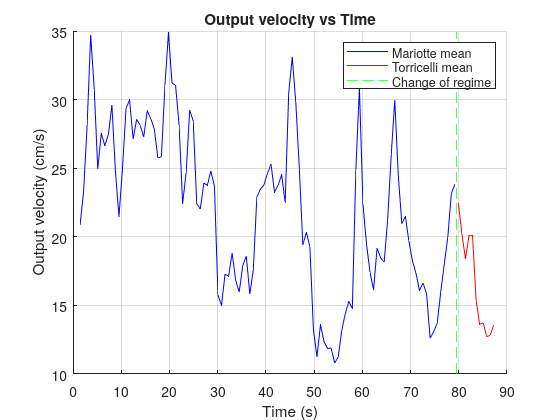

figure();
hold on;
plot(tMean(tMean < changeMean), vOutMean(tMean < changeMean), 'b-', 'DisplayName', 'Mariotte mean');
plot(tMean(tMean > changeMean), vOutMean(tMean > changeMean), 'r-', 'DisplayName', 'Torricelli mean');
title('Output velocity vs Time');
xlabel("Time (s)");
ylabel("Output velocity (cm/s)");
xline(changeMean, '--g', 'DisplayName', 'Change of regime');
legend();
grid on;
hold off;

### Case 1 

Water level velocity vs time

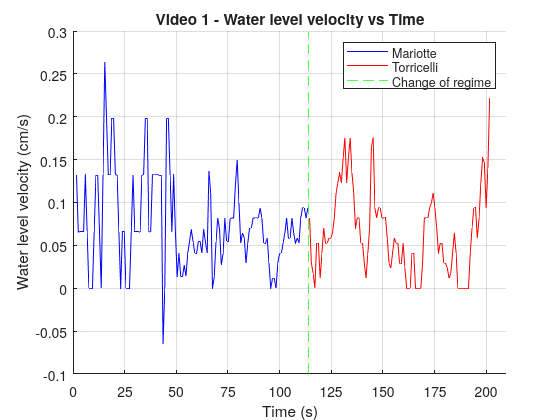

figure();
hold on;
plot(t1(t1 < change1), vLevel1(t1 < change1), 'b-', 'DisplayName', 'Mariotte');
plot(t1(t1 > change1), vLevel1(t1 > change1), 'r-', 'DisplayName', 'Torricelli');
xline(change1, '--g', 'DisplayName', 'Change of regime');
title('Video 1 - Water level velocity vs Time');
xlabel("Time (s)");
ylabel("Water level velocity (cm/s)");
xlim([0 210]);
xticks(0:25:210);
legend();
grid on;
hold off;

Output velocity vs time

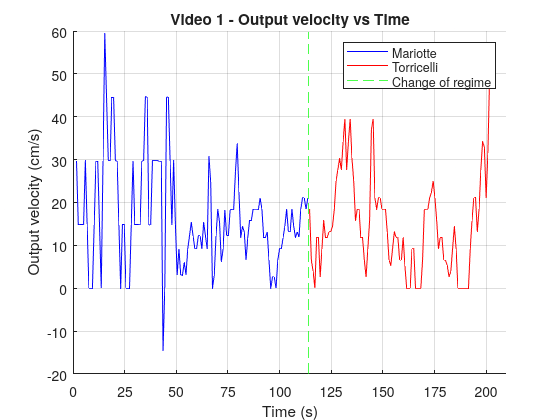

figure();
hold on;
plot(t1(t1 < change1), vOut1(t1 < change1), 'b-', 'DisplayName', 'Mariotte');
plot(t1(t1 > change1), vOut1(t1 > change1), 'r-', 'DisplayName', 'Torricelli');
xline(change1, '--g', 'DisplayName', 'Change of regime');
title('Video 1 - Output velocity vs Time');
xlabel("Time (s)");
ylabel("Output velocity (cm/s)");
xlim([0 210]);
xticks(0:25:210);
legend();
grid on;
hold off;

### Case 2

Water level velocity vs time

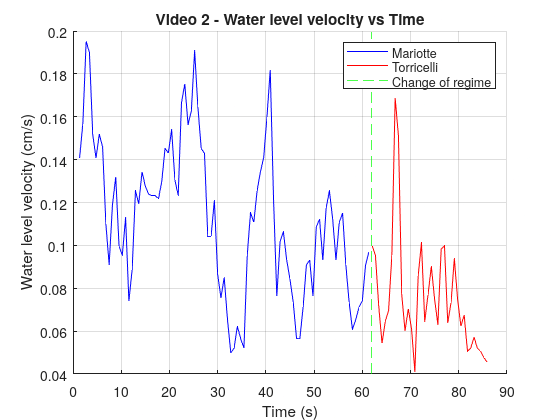

figure();
hold on;
plot(t2(t2 < change2), vLevel2(t2 < change2), 'b-', 'DisplayName', 'Mariotte');
plot(t2(t2 > change2), vLevel2(t2 > change2), 'r-', 'DisplayName', 'Torricelli');
xline(change2, '--g', 'DisplayName', 'Change of regime');
title('Video 2 - Water level velocity vs Time');
xlabel("Time (s)");
ylabel("Water level velocity (cm/s)");
xlim([0 90]);
legend();
grid on;
hold off;

Output velocity vs time

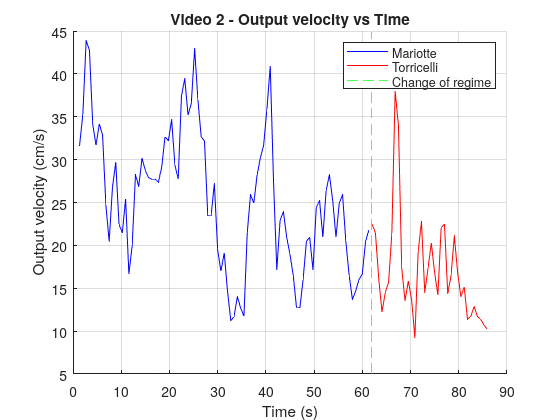

figure();
hold on;
plot(t2(t2 < change2), vOut2(t2 < change2), 'b-', 'DisplayName', 'Mariotte');
plot(t2(t2 > change2), vOut2(t2 > change2), 'r-', 'DisplayName', 'Torricelli');
xline(change2, '--g', 'DisplayName', 'Change of regime');
title('Video 2 - Output velocity vs Time');
xlabel("Time (s)");
ylabel("Output velocity (cm/s)");
xlim([0 90]);
legend();
grid on;
hold off;

### Case 3

Water level velocity vs time

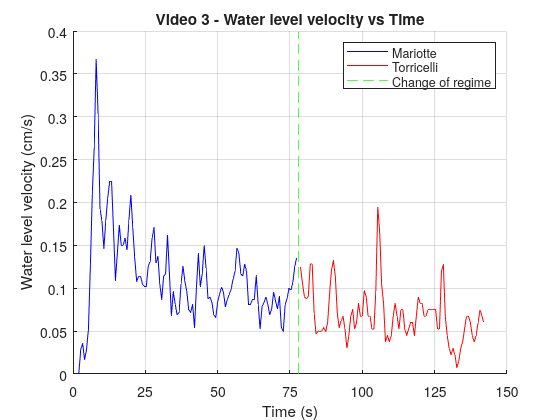

figure();
hold on;
plot(t3(t3 < change3), vLevel3(t3 < change3), 'b-', 'DisplayName', 'Mariotte');
plot(t3(t3 > change3), vLevel3(t3 > change3), 'r-', 'DisplayName', 'Torricelli');
xline(change3, '--g', 'DisplayName', 'Change of regime');
title('Video 3 - Water level velocity vs Time');
xlabel("Time (s)");
ylabel("Water level velocity (cm/s)");
xlim([0 150]);
xticks(0:25:150);
legend();
grid on;
hold off;

Output velocity vs time

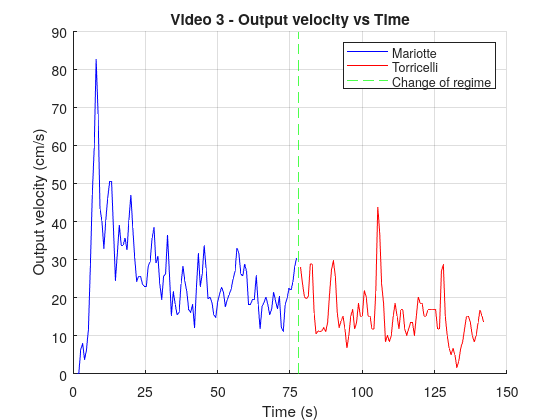

figure();
hold on;
plot(t3(t3 < change3), vOut3(t3 < change3), 'b-', 'DisplayName', 'Mariotte');
plot(t3(t3 > change3), vOut3(t3 > change3), 'r-', 'DisplayName', 'Torricelli');
xline(change3, '--g', 'DisplayName', 'Change of regime');
title('Video 3 - Output velocity vs Time');
xlabel("Time (s)");
ylabel("Output velocity (cm/s)");
xlim([0 150]);
xticks(0:25:150);
legend();
grid on;
hold off;

### Case 4

Water level velocity vs time

min(t4)

ans = 0

max(t4)

ans = 141.3330

length(t4)

ans = 213


length(t4(t4 < change4))

ans = 91

length(t4(t4 > change4))

ans = 121

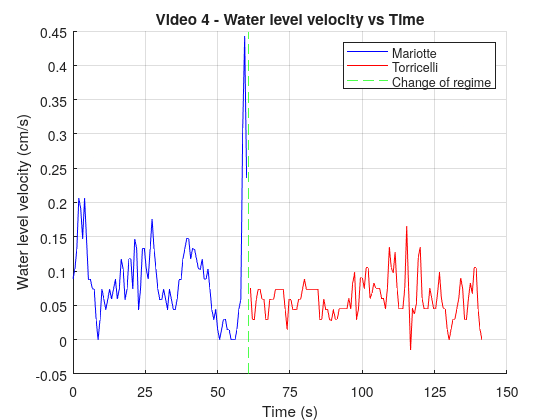

figure();
hold on;
plot(t4(t4 < change4), vLevel4(t4 < change4), 'b-', 'DisplayName', 'Mariotte');
plot(t4(t4 > change4), vLevel4(t4 > change4), 'r-', 'DisplayName', 'Torricelli');
xline(change4, '--g', 'DisplayName', 'Change of regime');
title('Video 4 - Water level velocity vs Time');
xlabel("Time (s)");
ylabel("Water level velocity (cm/s)");
xticks(0:25:150);
legend();
grid on;
hold off;

Output velocity vs time

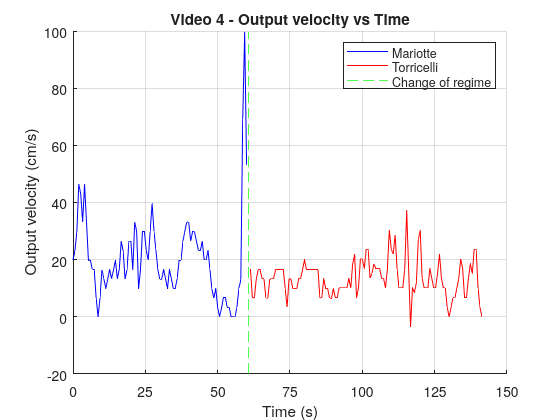

figure();
hold on;
plot(t4(t4 < change4), vOut4(t4 < change4), 'b-', 'DisplayName', 'Mariotte');
plot(t4(t4 > change4), vOut4(t4 > change4), 'r-', 'DisplayName', 'Torricelli');
xline(change4, '--g', 'DisplayName', 'Change of regime');
title('Video 4 - Output velocity vs Time');
xlabel("Time (s)");
ylabel("Output velocity (cm/s)");
xticks(0:25:150);
legend();
grid on;
hold off;

### Case 5

Water level velocity vs time

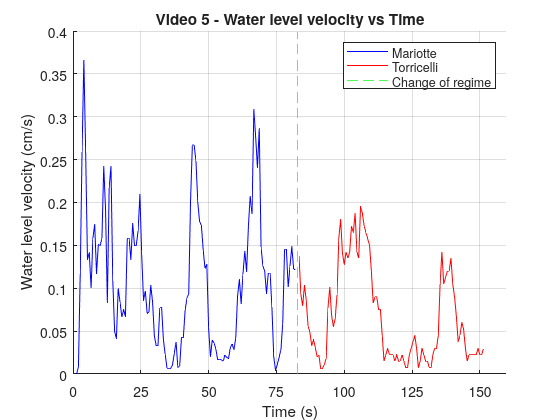

figure();
hold on;
plot(t5(t5 < change5), vLevel5(t5 < change5), 'b-', 'DisplayName', 'Mariotte');
plot(t5(t5 > change5), vLevel5(t5 > change5), 'r-', 'DisplayName', 'Torricelli');
xline(change5, '--g', 'DisplayName', 'Change of regime');
title('Video 5 - Water level velocity vs Time');
xlabel("Time (s)");
ylabel("Water level velocity (cm/s)");
xlim([0 160]);
xticks(0:25:160);
legend();
grid on;
hold off;

Output velocity vs time

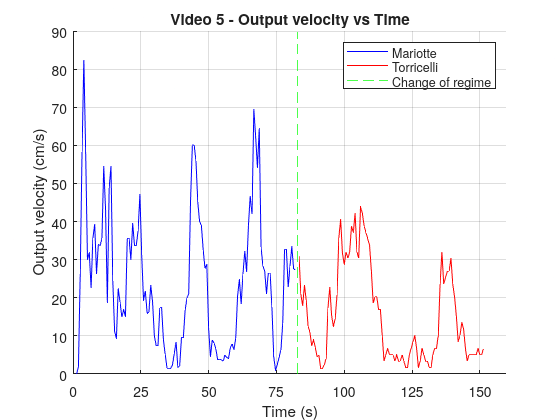

figure();
hold on;
plot(t5(t5 < change5), vOut5(t5 < change5), 'b-', 'DisplayName', 'Mariotte');
plot(t5(t5 > change5), vOut5(t5 > change5), 'r-', 'DisplayName', 'Torricelli');
xline(change5, '--g', 'DisplayName', 'Change of regime');
title('Video 5 - Output velocity vs Time');
xlabel("Time (s)");
ylabel("Output velocity (cm/s)");
xlim([0 160]);
xticks(0:25:160);
legend();
grid on;
hold off;